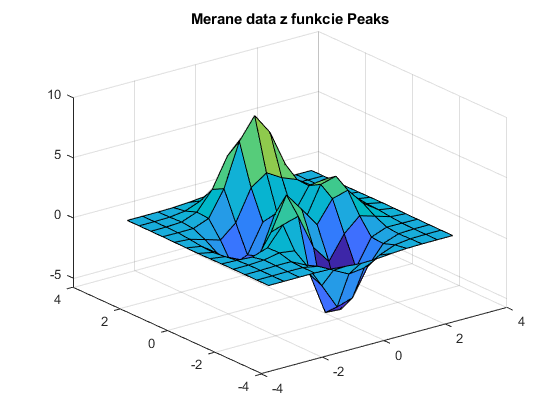

% Demonštračný príklad aproximácie 2D funkcie PEAKS 
% neuronovou sieťou typu RBF

% Zobrazenie funkcie peaks
% z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ...
%   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ...
%   - 1/3*exp(-(x+1).^2 - y.^2);
[x,y]=meshgrid(-3:0.5:3);
z=peaks(x,y);
figure
surf(x,y,z)
title('Merane data z funkcie Peaks')

NEWRB, neurons = 0, MSE = 3.11336
NEWRB, neurons = 50, MSE = 0.00106616


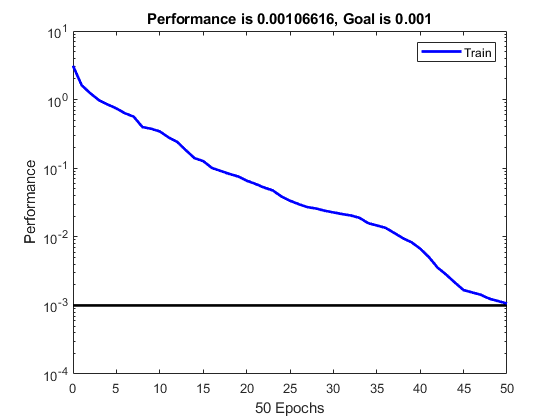

% Vytvorenie vstupnych a vystupnych dat NS z meranych dat (trenovacie data)
innet=[x(1,:); y(1,:)];
outnet=[z(1,:)];
n=size(x,1);
for k=2:n
    innet=[innet(1,:) x(k,:);innet(2,:) y(k,:)];
    outnet=[outnet(1,:) z(k,:)];
end

% Vytvorenie vstupnych dat NS na interpolaciu (testovacie data)
[xi,yi]=meshgrid(-3:0.25:3);
innet2=[xi(1,:); yi(1,:)];
m=size(xi,1);
for k=2:m
    innet2=[innet2(1,:) xi(k,:);innet2(2,:) yi(k,:)];
end

% vytvorenie a trenovanie RBF siete
net = newrb(innet,outnet,0.001);       % alebo net = newrb(innet,outnet,0.00001,1,150,10);


% simulacia vystupu NS pre trenovacie data
outnetsim = sim(net,innet);

% simulacia vystupu NS pre testovacie data
outnetsim2 = sim(net,innet2);

% prepis do 3D formy
zsim=[];
for k=1:n
    zsim(k,:)=outnetsim(((k-1)*n+1):k*n);    
end
zsim2=[];
for k=1:m
    zsim2(k,:)=outnetsim2(((k-1)*m+1):k*m);    
end

% vypocet chyby - odchylok na trénovacích datach
errSSE_train=sum(sum((z-zsim).^2))

errSSE_train = 0.1605

errMSE_train=errSSE_train/(n*n)

errMSE_train = 9.4985e-04


% vypocet chyby - odchylok na testovacích datach
zi=peaks(xi,yi);
errSSE_test=sum(sum((zi-zsim2).^2))

errSSE_test = 1.6709

errMSE_test=errSSE_test/(m*m)

errMSE_test = 0.0027

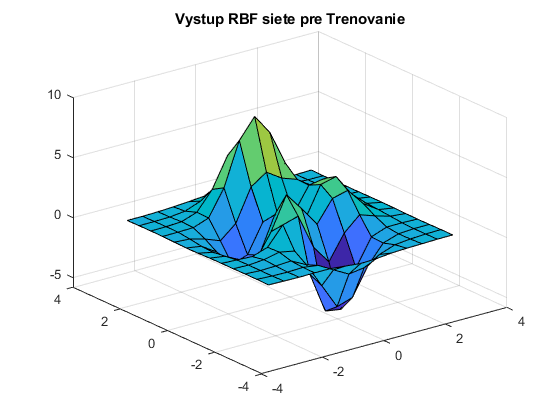



% Zobrazenie vystupu RBF siete na trenovacich datach
figure
surf(x,y,zsim)
title('Vystup RBF siete pre Trenovanie')

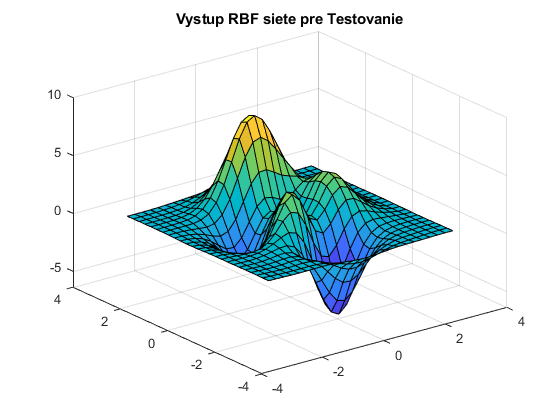

% Zobrazenie vystupu RBF siete na testovacich datach
% interpolacia funkcie
figure
surf(xi,yi,zsim2)
title('Vystup RBF siete pre Testovanie')